# Geom-SINDy DSI vs SINDy DSI (consider ideal T&N space) - Set up at 2024May5

This version try to use high order solver ode45

clear
clc

rng(1)

## Initialization

global n% ambient space dimension
global d% manifold dimension
global Xnoise
global Pnum
global index
global Dt

% Pnum=4000*2.5;%number of samples in training set
n=3;% ambient space dimension
d=2;% manifold dimension

## 1 Data set generation

#### Generate sample data set - Spring torus curve

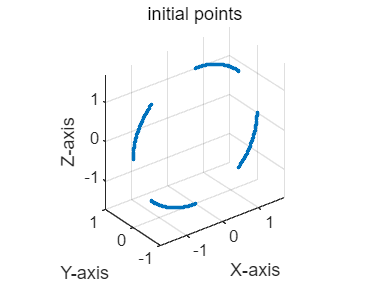

CycNum=1;%cycle number

t_total=20*2;
dt=1e-3;
t=0:dt:t_total;

I1=1.6;
I2=1;
I3=0.72;
PnumTol=size(t,2);

Cf=3/2;% take advantage of the energy radius of this Eular's equation of motion
r=sqrt(2*Cf);

curveNum = 200; % number of curves (must be multiple of 8)

% Generate evenly distributed points on the unit sphere
num_points = curveNum;
theta = 0;%绕z轴的角度（经度）
phi = linspace(0, 1*pi/4, num_points/4);%与z轴的夹角（纬度）
phi = [phi linspace(2*pi/4, 3*pi/4, num_points/4)];
phi = [phi linspace(4*pi/4, 5*pi/4, num_points/4)];
phi = [phi linspace(6*pi/4, 7*pi/4, num_points/4)];
x1 = r*sin(phi).*cos(theta);
x2 = r*sin(phi).*sin(theta);
x3 = r*cos(phi);

figure
plot3(x1,x2,x3,'.');title('initial points')
grid on;
axis equal; % Make sure the aspect ratio is the same for all axes
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');

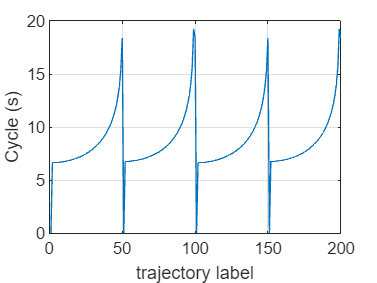


DataCloud = cell(1,curveNum); % preallocate cell array

for curN = 1:num_points
    X = zeros(n, PnumTol);
    X(:, 1) = [x1(curN); x2(curN); x3(curN)];
    
    for j = 1:PnumTol-1
        X1_hat = X(1, j) + dt*(1/I3-1/I2)*X(2, j)*X(3, j);
        X2_hat = X(2, j) + dt*(1/I1-1/I3)*X(1, j)*X(3, j);
        X3_hat = X(3, j) + dt*(1/I2-1/I1)*X(2, j)*X(1, j);
        X(1, j+1) = X(1, j) + dt*(1/I3-1/I2)*(X2_hat+X(2, j))/2*(X3_hat+X(3, j))/2;
        X(2, j+1) = X(2, j) + dt*(1/I1-1/I3)*(X1_hat+X(1, j))/2*(X3_hat+X(3, j))/2;
        X(3, j+1) = X(3, j) + dt*(1/I2-1/I1)*(X2_hat+X(2, j))/2*(X1_hat+X(1, j))/2;
        X(:,j+1)=X(:,j+1)/norm(X(:,j+1))*r;
    end
    
    DataCloud{curN} = X;
end

curvePointsPerCyc=[];
for curN=1:curveNum
    indices=[];
    queryPoint=DataCloud{curN}(:,1)';
    [indices, distances] = knnsearch(DataCloud{curN}', queryPoint, 'K', 10);
    indices(indices==1)=[];
    indices=sort(indices);
    if indices(1,2)/indices(1,1)>100
        curvePointsPerCyc(curN)=indices(1,2);
    else
        curvePointsPerCyc(curN)=indices(1,1);
    end
end
curvePointsPerCyc(1)=2;
curvePointsPerCyc(curveNum/4+1)=2;
curvePointsPerCyc(curveNum/2+1)=2;
curvePointsPerCyc(curveNum/4*3+1)=2;
Tcyc=(curvePointsPerCyc-1)*dt;

plot(Tcyc);
grid on
xlabel('trajectory label');ylabel('Cycle (s)')

% title('cycle of each trajectory')

#### Display

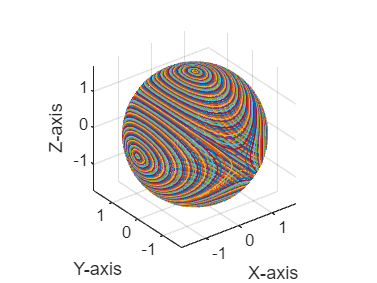

% Plot the manifold in 3D space
figure
for i=1:curveNum
plot3(DataCloud{i}(1,1:100:end), DataCloud{i}(2,1:100:end), DataCloud{i}(3,1:100:end));
hold on
end
hold off
grid on;
axis equal; % Make sure the aspect ratio is the same for all axes
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');

% title('simulate data');

#### Sampling

part=1;

sp=50*20;% sampling muliple of simulation rate
Dt=sp*dt;

Pnum=round(CycNum*Tcyc/Dt+1);% curve points per cycle after sampling

Xnoise={};
Xsp={};
Xtrain={};
Xtest={};
Xsp_Together=[];
curN1=1;
curN2=1;
for curN=1:curveNum
    Xsp{curN}=zeros(n,Pnum(1,curN));
    for i=1:Pnum(1,curN)
        Xsp{curN}(:,i)=DataCloud{curN}(:,1+(i-1)*sp);% one cycle window length
    end
end

Xtrain=Xsp(1,1:2:end);curveNumTrain=size(Xtrain,2);
Xtest=Xsp(1,2:2:end);curveNumTest=size(Xtest,2);

for curN=1:curveNum
for i=1:floor(PnumTol/sp)
    Xsp_total{curN}(:,i)=DataCloud{curN}(:,1+(i-1)*sp);%full window length
end
end

Xtrain_total=Xsp_total(1,1:2:end);
Xtest_total=Xsp_total(1,2:2:end);

for curN=1:curveNum
Xsp_Together=[Xsp_Together Xsp{curN}];% knn search base
end

#### Display

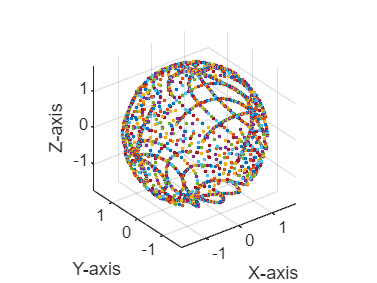

% Plot the manifold in 3D space
figure
for curN=1:curveNumTrain
plot3(Xtrain{curN}(1,:), Xtrain{curN}(2,:), Xtrain{curN}(3,:),'.');hold on
end
for curN=1:curveNumTest
plot3(Xtest{curN}(1,:), Xtest{curN}(2,:), Xtest{curN}(3,:),'.');hold on
end

grid on;hold off
axis equal; % Make sure the aspect ratio is the same for all axes
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');

## 2 SINDy model building

Prepare the tangent and normal space for training

Pn=sum(Pnum);
knear=round(Pn^0.5);

Tbox={};Ttrain={};
Nbox={};Ntrain={};

for curN=1:curveNum
    for i=1:Pnum(1,curN)
        [Tbox{curN,i},Nbox{curN,i}]=TNspace_EulerSphere_Ideal(Xsp{curN}(:,i));
    end
end
count=0;
for curN=1:curveNumTrain
Ttrain{curN}=Tbox(1+count,:);
Ntrain{curN}=Nbox(1+count,:);
count=count+2;
end
count=0;
for curN=1:curveNumTest
Ttest{curN}=Tbox(2+count,:);
Ntest{curN}=Nbox(2+count,:);
count=count+2;
end

Solve the GeoSINDy model

Numtrain=sum(Pnum(1:2:end));% number of points in training set
Klib=1+3*n;% number of candidate function
dotX_trainMatrix=zeros(Numtrain,n);
library_trainMatrix=[];

dotXtrain={};dotXtrain_T_amb={};
for curN=1:curveNumTrain
if curN==0+1||curN==curveNumTrain/4+1||curN==curveNumTrain/2+1||curN==curveNumTrain/4*3+1
    dotXtrain{curN}=zeros(n,1);
else
    PreStepMatrix=Xtrain{curN};
    NextStepMatrix=Xtrain{curN};
    PreStepMatrix(:,end)=[];
    NextStepMatrix(:,1)=[];
    dotXtrain{curN}=(NextStepMatrix-PreStepMatrix)/Dt;

    flag=ones(size(Pnum(1,1:2:end)));flag(1,1)=0;flag(1,curveNumTrain/4+1)=0;flag(1,curveNumTrain/2+1)=0;flag(1,curveNumTrain/4*3+1)=0;
    flagf=Pnum(1,1:2:end)-flag;
    for i=1:flagf(1,curN)
        T=Ttrain{curN};
        dotXtrain_T_amb{curN}(:,i)=T{i}*T{i}'*dotXtrain{curN}(:,i);
    end
end
end

dotXtrain_T_amb{1}=zeros(n,1);
dotXtrain_T_amb{curveNumTrain/4+1}=zeros(n,1);
dotXtrain_T_amb{curveNumTrain/2+1}=zeros(n,1);
dotXtrain_T_amb{curveNumTrain/4*3+1}=zeros(n,1);

dotXtrainTambMatrix=[];
for i=1:curveNumTrain
    dotXtrainTambMatrix=[dotXtrainTambMatrix dotXtrain_T_amb{i}];
end
dotXtrainTambMatrix=dotXtrainTambMatrix';

XtrainMatrix=[];
for curN=1:curveNumTrain
    if curN==0+1||curN==curveNumTrain/4+1||curN==curveNumTrain/2+1||curN==curveNumTrain/4*3+1
        XtrainMatrix=[XtrainMatrix Xtrain{curN}];
    else
        XtrainMatrix=[XtrainMatrix Xtrain{curN}(:,1:end-1)];
    end
end
for i=1:size(XtrainMatrix,2)
    library_trainMatrix(i,:)=CandidateFunVector(XtrainMatrix(:,i));
end


lambda=1e-4;
Coef_IdlGeomSINDy = sparsifyDynamics(library_trainMatrix,dotXtrainTambMatrix,lambda,n)

Coef_IdlGeomSINDy =          0         0         0
    0.0377         0   -0.0005
         0   -0.1139         0
   -0.0002         0    0.0405
         0   -0.0003         0
         0         0         0
         0    0.0002         0
    0.0003         0    0.3534
    0.3655         0   -0.0007
         0   -0.6798         0


Solve the SINDy model

Ntrain=sum(Pnum(1:2:end));% number of points in training set
Klib=1+3*n;% number of candidate function
dotX_trainMatrix=zeros(Ntrain,n);

dotXtrainMatrix=[];
for i=1:curveNumTrain
    dotXtrainMatrix=[dotXtrainMatrix dotXtrain{i}];
end
dotXtrainMatrix=dotXtrainMatrix';

lambda=1e-4;
Coef_IdlSINDy = sparsifyDynamics(library_trainMatrix,dotXtrainMatrix,lambda,n)

Coef_IdlSINDy =          0         0         0
   -0.0316         0   -0.0008
         0   -0.1794         0
   -0.0006         0   -0.0295
         0   -0.0004         0
         0    0.0001         0
         0    0.0002         0
   -0.0005         0    0.3353
    0.3474         0   -0.0007
         0   -0.6976         0


## 3 Prediction 

#### Purely prediction without correction algorithm in each step

Predict a trajectory traveling on the manifold **only given the initial points**.

GeoSINDy model:

Xpre={};
error_GeoSINDy={};
usesine=0;
polyorder=1;

for curN=1:curveNumTest
Xpre{curN}=zeros(size(Xtest{curN}));
Xpre{curN}(:,1)=Xtest{curN}(:,1);%+0.002*randn(size(X(:,1:1+shiftStr)));

%=====mode selecting========
% nodes=size(Xtest{curN},2);% one cycle for each curve
nodes=size(Xtest{curveNumTest},2);% The same time length for all curve (at leaset 1 cycle of the biggest curve)
%================

degr=3;% GMLS parameter

error_GeoSINDy{curN}=zeros(1,nodes+1);
errorOffManifold_GeoSINDy{curN}=zeros(1,nodes+1);
for i=1:nodes
    % =================Calculate Ti and Ni===================
    % queryPoint=Xpre{curN}(:,i)';
    % [indices, distances] = knnsearch(Xsp_Together', queryPoint, 'K', knear);
    % DistPoint=Xsp_Together(:,indices);
    % Dist=DistPoint-queryPoint';
    % [U,S,Vt]=svd(Dist);
    % U=SVD_U_SignAlignment(U);
    % Ti=U(:,1:d);%n*d
    % Ni=U(:,d+1:n);%n*(n-d)
    % 
    % Tisee{i}=Ti;
    % Nisee{i}=Ni;
    % 
    % xi=Xpre{curN}(:,i);
    % dXTambpDt=(CandidateFunVector(xi)*Coef_IdlGeomSINDy)';
    % dXTamb=dXTambpDt*Dt;
    % dXNamb=GMLS_for_VerticalInc(Dist,Ti,Ni,dXTamb)
    % dX=dXTamb+dXNamb;
    % ===================================================
    
    % =========use ideal way to obtain Ti and Ni============
    % xi=Xpre{curN}(:,i);
    % [Ti,Ni]=TNspace_EulerSphere_Ideal(xi);
    % 
    % dXTambpDt=(CandidateFunVector(xi)*Coef_IdlGeomSINDy)';
    % dXpDt=dXTambpDt;
    % dXTamb=dXTambpDt*Dt;
    % queryPoint=xi';
    % 
    % [indices, distances] = knnsearch(Xsp_Together', queryPoint, 'K', knear);
    % DistPoint=Xsp_Together(:,indices);
    % Dist=DistPoint-queryPoint';
    % dXNamb=GMLS_for_VerticalInc(Dist,Ti,Ni,dXTamb,degr,knear,d);% here we still must use GMLS since we cannot determine ideal normal increment as we cannot get xi+1 ideally (if so the test will become meanless and always zero error)
    % dX=dXTamb+dXNamb;
    % ===================================================

    % ===========use ideal way to obtain Ti and Ni and vertical increment (this offline method very bad)==========
    % xi=Xpre{curN}(:,i);
    % [Ti,Ni]=TNspace_EulerSphere_Ideal(xi);
    % dXTambpDt=(CandidateFunVector(xi)*Coef_IdlGeomSINDy)';
    % dXTamb=dXTambpDt*Dt;
    % dXNamb=Ni*Ni'*(Xtest_total{curN}(:,i+1)-xi);
    % dX=dXTamb+dXNamb;
    % ===================================================

    % ============use high order methods directly ode45===========================
    xi=Xpre{curN}(:,i);
    [Ti,Ni]=TNspace_EulerSphere_Ideal(xi);

    dXTambpDt=(CandidateFunVector(xi)*Coef_IdlGeomSINDy)';
    dotX1=dXTambpDt;
    
    xi1=xi+0.5*Dt*dotX1;
    dotX2=(CandidateFunVector(xi1)*Coef_IdlGeomSINDy)';

    xi2=xi+0.5*Dt*dotX2;
    dotX3=(CandidateFunVector(xi2)*Coef_IdlGeomSINDy)';

    xi3=xi+Dt*dotX3;
    dotX4=(CandidateFunVector(xi3)*Coef_IdlGeomSINDy)';

    dX=Dt/6*(dotX1+dotX2*2+dotX3*2+dotX4);
    % ===================================================

    Xpre{curN}(:,i+1)=Xpre{curN}(:,i)+dX;
  
    error_GeoSINDy{curN}(i+1)=norm(Xpre{curN}(:,i+1)-Xtest_total{curN}(:,i+1))/r;
    errorOffManifold_GeoSINDy{curN}(i+1)=abs(norm(Xpre{curN}(:,i+1))-r)/r;
end
e=max(error_GeoSINDy{curN})
eOffMan=max(errorOffManifold_GeoSINDy{curN})

fig=0;
if fig==1
    curN
figure
plot3(Xpre{curN}(1,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1), Xpre{curN}(2,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1), Xpre{curN}(3,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1),'.','Linewidth', 0.1);title('prediction performance')
hold on
plot3(Xtest_total{curN}(1,1:nodes), Xtest_total{curN}(2,1:nodes), Xtest_total{curN}(3,1:nodes),'.','Linewidth', 5);legend('esti-curve','sample-curve')
hold off
figure
plot3(Xpre{curN}(1,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1), Xpre{curN}(2,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1), Xpre{curN}(3,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1));title('prediction performance')
figure
plot(error_GeoSINDy{curN}(1,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1));title('relative error for each step')
end

end

e = 1.1566

eOffMan = 1.1563

e = 1.1551

eOffMan = 1.1522

e = 1.1522

eOffMan = 1.1440

e = 1.1483

eOffMan = 1.1316

e = 1.1437

eOffMan = 1.1150

e = 1.1386

eOffMan = 1.0941

e = 1.1329

eOffMan = 1.0691

e = 1.1254

eOffMan = 1.0398

e = 1.1143

eOffMan = 1.0062

e = 1.0961

eOffMan = 0.9681

e = 1.0676

eOffMan = 0.9250

e = 1.0726

eOffMan = 0.8768

e = 1.1243

eOffMan = 0.8242

e = 1.1431

eOffMan = 0.7678

e = 1.1875

eOffMan = 0.7069

e = 1.2186

eOffMan = 0.6380

e = 1.2627

eOffMan = 0.5618

e = 1.2387

eOffMan = 0.4843

e = 1.1867

eOffMan = 0.3989

e = 1.2025

eOffMan = 0.2952

e = 1.2288

eOffMan = 0.1936

e = 1.0381

eOffMan = 0.1295

e = 0.6611

eOffMan = 0.2045

e = 0.6309

eOffMan = 0.3144

e = 0.8245

eOffMan = 0.5393

e = 1.0475

eOffMan = 1.0471

e = 1.0466

eOffMan = 1.0430

e = 1.0449

eOffMan = 1.0348

e = 1.0428

eOffMan = 1.0225

e = 1.0408

eOffMan = 1.0060

e = 1.0390

eOffMan = 0.9853

e = 1.0369

eOffMan = 0.9604

e = 1.0330

eOffMan = 0.9310

e = 1.0240

eOffMan = 0.8971

e = 1.0059

eOffMan = 0.8586

e = 1.0237

eOffMan = 0.8158

e = 1.0684

eOffMan = 0.7691

e = 1.0788

eOffMan = 0.7182

e = 1.1471

eOffMan = 0.6612

e = 1.1718

eOffMan = 0.5965

e = 1.2302

eOffMan = 0.5272

e = 1.2091

eOffMan = 0.4562

e = 1.0661

eOffMan = 0.3750

e = 1.0613

eOffMan = 0.2788

e = 1.0694

eOffMan = 0.1862

e = 0.9973

eOffMan = 0.1179

e = 0.5574

eOffMan = 0.1850

e = 0.5915

eOffMan = 0.2843

e = 0.9226

eOffMan = 0.4556

e = 0.8834

eOffMan = 0.5543

e = 1.1566

eOffMan = 1.1563

e = 1.1551

eOffMan = 1.1522

e = 1.1522

eOffMan = 1.1440

e = 1.1483

eOffMan = 1.1316

e = 1.1437

eOffMan = 1.1150

e = 1.1386

eOffMan = 1.0941

e = 1.1329

eOffMan = 1.0691

e = 1.1254

eOffMan = 1.0398

e = 1.1143

eOffMan = 1.0062

e = 1.0961

eOffMan = 0.9681

e = 1.0676

eOffMan = 0.9250

e = 1.0726

eOffMan = 0.8768

e = 1.1243

eOffMan = 0.8242

e = 1.1431

eOffMan = 0.7678

e = 1.1875

eOffMan = 0.7069

e = 1.2186

eOffMan = 0.6380

e = 1.2627

eOffMan = 0.5618

e = 1.2387

eOffMan = 0.4843

e = 1.1867

eOffMan = 0.3989

e = 1.2025

eOffMan = 0.2952

e = 1.2288

eOffMan = 0.1936

e = 1.0381

eOffMan = 0.1295

e = 0.6611

eOffMan = 0.2045

e = 0.6309

eOffMan = 0.3144

e = 0.8245

eOffMan = 0.5393

e = 1.0475

eOffMan = 1.0471

e = 1.0466

eOffMan = 1.0430

e = 1.0449

eOffMan = 1.0348

e = 1.0428

eOffMan = 1.0225

e = 1.0408

eOffMan = 1.0060

e = 1.0390

eOffMan = 0.9853

e = 1.0369

eOffMan = 0.9604

e = 1.0330

eOffMan = 0.9310

e = 1.0240

eOffMan = 0.8971

e = 1.0059

eOffMan = 0.8586

e = 1.0237

eOffMan = 0.8158

e = 1.0684

eOffMan = 0.7691

e = 1.0788

eOffMan = 0.7182

e = 1.1471

eOffMan = 0.6612

e = 1.1718

eOffMan = 0.5965

e = 1.2302

eOffMan = 0.5272

e = 1.2091

eOffMan = 0.4562

e = 1.0661

eOffMan = 0.3750

e = 1.0613

eOffMan = 0.2788

e = 1.0694

eOffMan = 0.1862

e = 0.9973

eOffMan = 0.1179

e = 0.5574

eOffMan = 0.1850

e = 0.5915

eOffMan = 0.2843

e = 0.9226

eOffMan = 0.4556

e = 0.8834

eOffMan = 0.5543

SINDy model:

Xpre={};
errorOnly_SINDy={};
usesine=0;
polyorder=2;%lirary function order

for curN=1:curveNumTest
Xpre{curN}=zeros(size(Xtest{curN}));
Xpre{curN}(:,1)=Xtest{curN}(:,1);%+0.002*randn(size(X(:,1:1+shiftStr)));

%=====mode selecting========
% nodes=size(Xtest{curN},2);% one cycle for each curve
nodes=size(Xtest{curveNumTest},2);% The same time length for all curve (at leaset 1 cycle of the biggest curve)
%================

errorOnly_SINDy{curN}=zeros(1,nodes+1);
errorOffManifoldOnly_SINDy{curN}=zeros(1,nodes+1);
% ====================1st order Euler===================
% for i=1:nodes%Pnum-1
%     xi=Xpre{curN}(:,i);
%     dXpDt=(CandidateFunVector(xi)*Coef_IdlSINDy)';
%     Xpre{curN}(:,i+1)=Xpre{curN}(:,i)+dXpDt*Dt;
% end
% ========================================================

% ===================ode45================================
for i=1:nodes%Pnum-1
    xi=Xpre{curN}(:,i);
    dXpDt=(CandidateFunVector(xi)*Coef_IdlSINDy)';
    dotX1=dXpDt;

    xi1=xi+0.5*Dt*dotX1;
    dotX2=(CandidateFunVector(xi1)*Coef_IdlSINDy)';

    xi2=xi+0.5*Dt*dotX2;
    dotX3=(CandidateFunVector(xi2)*Coef_IdlSINDy)';

    xi3=xi+Dt*dotX3;
    dotX4=(CandidateFunVector(xi3)*Coef_IdlSINDy)';

    dX=Dt/6*(dotX1+dotX2*2+dotX3*2+dotX4);

    Xpre{curN}(:,i+1)=Xpre{curN}(:,i)+dX;
end
% ========================================================

errorOnly_SINDy{curN}=vecnorm((Xpre{curN}-Xtest_total{curN}(:,1:size(Xpre{curN},2))),2)/r;
errorOffManifoldOnly_SINDy{curN}=abs(vecnorm(Xpre{curN})-r)/r;

e=max(errorOnly_SINDy{curN})
eOffMan=max(errorOffManifoldOnly_SINDy{curN})

fig=0;
if fig==1
    curN
figure
plot3(Xpre{curN}(1,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1), Xpre{curN}(2,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1), Xpre{curN}(3,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1),'.','Linewidth', 0.1);title('prediction performance')
hold on
plot3(Xtest_total{curN}(1,1:nodes), Xtest_total{curN}(2,1:nodes), Xtest_total{curN}(3,1:nodes),'.','Linewidth', 5);legend('esti-curve','sample-curve')
hold off
figure
plot3(Xpre{curN}(1,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1), Xpre{curN}(2,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1), Xpre{curN}(3,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1));title('prediction performance')
figure
plot(errorOnly_SINDy{curN}(1,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1));title('relative error for each step')
end

end

e = 0.4298

eOffMan = 0.4296

e = 0.4325

eOffMan = 0.4307

e = 0.4380

eOffMan = 0.4328

e = 0.4464

eOffMan = 0.4361

e = 0.4577

eOffMan = 0.4404

e = 0.4715

eOffMan = 0.4459

e = 0.4872

eOffMan = 0.4525

e = 0.5117

eOffMan = 0.4601

e = 0.5488

eOffMan = 0.4689

e = 0.5876

eOffMan = 0.4787

e = 0.6351

eOffMan = 0.4896

e = 0.6878

eOffMan = 0.5015

e = 0.7321

eOffMan = 0.5146

e = 0.7621

eOffMan = 0.5292

e = 0.8143

eOffMan = 0.5458

e = 0.8492

eOffMan = 0.5647

e = 0.8822

eOffMan = 0.5859

e = 0.9069

eOffMan = 0.6083

e = 0.9540

eOffMan = 0.6303

e = 1.0013

eOffMan = 0.6518

e = 1.0446

eOffMan = 0.6773

e = 1.0877

eOffMan = 0.7146

e = 1.1106

eOffMan = 0.7612

e = 1.1083

eOffMan = 0.7886

e = 1.1008

eOffMan = 0.8611

e = 0.4513

eOffMan = 0.4511

e = 0.4542

eOffMan = 0.4522

e = 0.4597

eOffMan = 0.4544

e = 0.4678

eOffMan = 0.4578

e = 0.4782

eOffMan = 0.4622

e = 0.4902

eOffMan = 0.4678

e = 0.5029

eOffMan = 0.4744

e = 0.5241

eOffMan = 0.4821

e = 0.5627

eOffMan = 0.4910

e = 0.6145

eOffMan = 0.5008

e = 0.6646

eOffMan = 0.5118

e = 0.7080

eOffMan = 0.5241

e = 0.7393

eOffMan = 0.5378

e = 0.7908

eOffMan = 0.5534

e = 0.8290

eOffMan = 0.5711

e = 0.8572

eOffMan = 0.5907

e = 0.8908

eOffMan = 0.6112

e = 0.9394

eOffMan = 0.6314

e = 0.9791

eOffMan = 0.6512

e = 1.0384

eOffMan = 0.6743

e = 1.0806

eOffMan = 0.7082

e = 1.1099

eOffMan = 0.7536

e = 1.1121

eOffMan = 0.7873

e = 1.0909

eOffMan = 0.8123

e = 1.1022

eOffMan = 0.8637

e = 0.4298

eOffMan = 0.4296

e = 0.4325

eOffMan = 0.4307

e = 0.4380

eOffMan = 0.4328

e = 0.4464

eOffMan = 0.4361

e = 0.4577

eOffMan = 0.4404

e = 0.4715

eOffMan = 0.4459

e = 0.4872

eOffMan = 0.4525

e = 0.5117

eOffMan = 0.4601

e = 0.5488

eOffMan = 0.4689

e = 0.5876

eOffMan = 0.4787

e = 0.6351

eOffMan = 0.4896

e = 0.6878

eOffMan = 0.5015

e = 0.7321

eOffMan = 0.5146

e = 0.7621

eOffMan = 0.5292

e = 0.8143

eOffMan = 0.5458

e = 0.8492

eOffMan = 0.5647

e = 0.8822

eOffMan = 0.5859

e = 0.9069

eOffMan = 0.6083

e = 0.9540

eOffMan = 0.6303

e = 1.0013

eOffMan = 0.6518

e = 1.0446

eOffMan = 0.6773

e = 1.0877

eOffMan = 0.7146

e = 1.1106

eOffMan = 0.7612

e = 1.1083

eOffMan = 0.7886

e = 1.1008

eOffMan = 0.8611

e = 0.4513

eOffMan = 0.4511

e = 0.4542

eOffMan = 0.4522

e = 0.4597

eOffMan = 0.4544

e = 0.4678

eOffMan = 0.4578

e = 0.4782

eOffMan = 0.4622

e = 0.4902

eOffMan = 0.4678

e = 0.5029

eOffMan = 0.4744

e = 0.5241

eOffMan = 0.4821

e = 0.5627

eOffMan = 0.4910

e = 0.6145

eOffMan = 0.5008

e = 0.6646

eOffMan = 0.5118

e = 0.7080

eOffMan = 0.5241

e = 0.7393

eOffMan = 0.5378

e = 0.7908

eOffMan = 0.5534

e = 0.8290

eOffMan = 0.5711

e = 0.8572

eOffMan = 0.5907

e = 0.8908

eOffMan = 0.6112

e = 0.9394

eOffMan = 0.6314

e = 0.9791

eOffMan = 0.6512

e = 1.0384

eOffMan = 0.6743

e = 1.0806

eOffMan = 0.7082

e = 1.1099

eOffMan = 0.7536

e = 1.1121

eOffMan = 0.7873

e = 1.0909

eOffMan = 0.8123

e = 1.1022

eOffMan = 0.8637

## 4 Performance comparing

off manifold error

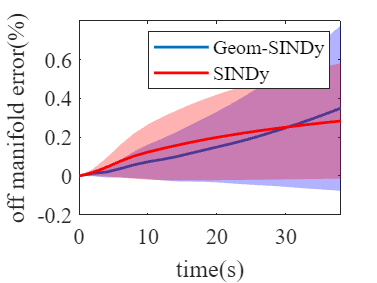

errorTN_SINDy1=errorOffManifold_GeoSINDy;

errorOnly_SINDy1=errorOffManifoldOnly_SINDy;


X_ErrorMatrix=zeros(curveNum,size(errorTN_SINDy1{1},2));

for curN=1:curveNumTest
X_ErrorMatrix(curN,:)=errorTN_SINDy1{curN};
end

steps=1:1:size(errorTN_SINDy1{curN},2);
X_AveError=mean(X_ErrorMatrix);

X_ErrorMatrixOnlySINDy=zeros(curveNum,size(errorOnly_SINDy1{1},2));

for curN=1:curveNumTest
X_ErrorMatrixOnlySINDy(curN,:)=errorOnly_SINDy1{curN};
end

steps=1:1:size(errorOnly_SINDy1{curN},2);
time=(steps-1)*2*Dt;

X_AveErrorOnlySINDy=mean(X_ErrorMatrixOnlySINDy);
frontsize=12;

figure%relative error sample 
f_upper=X_AveError+std(X_ErrorMatrix);f_lower=X_AveError-std(X_ErrorMatrix);
plot(time,X_AveError, 'LineWidth', 1.5);hold on;
fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'b', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold on;

f_upper=X_AveErrorOnlySINDy+std(X_ErrorMatrixOnlySINDy);f_lower=X_AveErrorOnlySINDy-std(X_ErrorMatrixOnlySINDy);
plot(time,X_AveErrorOnlySINDy, 'LineWidth', 1.5,'Color','r');hold on;
fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold off;

xlabel('time(s)');ylabel('off manifold error(%)');legend('Geom-SINDy','','SINDy')
set(gca, 'FontName', 'Times New Roman', 'FontSize', frontsize);xlim([0,time(end)])

% set(gca, 'YScale', 'log')

norm2 error

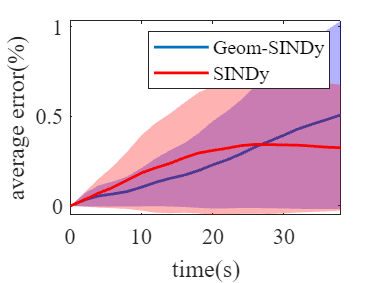

errorTN_SINDy2=error_GeoSINDy;

errorOnly_SINDy2=errorOnly_SINDy;


X_ErrorMatrix=zeros(curveNum,size(errorTN_SINDy2{1},2));

for curN=1:curveNumTest
X_ErrorMatrix(curN,:)=errorTN_SINDy2{curN};
end

steps=1:1:size(errorTN_SINDy2{curN},2);
X_AveError=mean(X_ErrorMatrix);

X_ErrorMatrixOnlySINDy=zeros(curveNum,size(errorOnly_SINDy2{1},2));

for curN=1:curveNumTest
X_ErrorMatrixOnlySINDy(curN,:)=errorOnly_SINDy2{curN};
end

steps=1:1:size(errorOnly_SINDy2{curN},2);
time=(steps-1)*2*Dt;

X_AveErrorOnlySINDy=mean(X_ErrorMatrixOnlySINDy);
frontsize=12;

figure%relative error sample 
f_upper=X_AveError+std(X_ErrorMatrix);f_lower=X_AveError-std(X_ErrorMatrix);
plot(time,X_AveError, 'LineWidth', 1.5);hold on;
fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'b', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold on;

f_upper=X_AveErrorOnlySINDy+std(X_ErrorMatrixOnlySINDy);f_lower=X_AveErrorOnlySINDy-std(X_ErrorMatrixOnlySINDy);
plot(time,X_AveErrorOnlySINDy, 'LineWidth', 1.5,'Color','r');hold on;
fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold off;

xlabel('time(s)');ylabel('average error(%)');legend('Geom-SINDy','','SINDy')
set(gca, 'FontName', 'Times New Roman', 'FontSize', frontsize);xlim([0,time(end)])